S = load('halleffect.mat');
rows = collectMeans(S, "");

meansTable = cell2table(rows, 'VariableNames', ...
    {'Variable', 'Start_s', 'End_s', 'Samples', 'Mean'});
disp(meansTable);

            Variable             Start_s    End_s     Samples       Mean   
    _________________________    _______    ______    _______    __________

    {'nonshield101.A0'      }       2.5        7.5     5001          4066.6
    {'nonshield101.Element2'}       2.5        7.5     5001        0.054238
    {'nonshield101.Element3'}       2.5        7.5     5001          3.2771
    {'nonshield102.A0'      }       2.5        7.5     5001          62.584
    {'nonshield102.Element2'}       2.5        7.5     5001       -0.053319
    {'nonshield102.Element3'}       2.5        7.5     5001        0.050434
    {'nonshield151.A0'      }       2.5        7.5     5001            4070
    {'nonshield151.Element2'}       2.5        7.5     5001        0.054329
    {'nonshield151.Element3'}       2.5        7.5     5001          


% วางฟังก์ชันทั้งหมดท้ายสคริปต์
function rows = collectMeans(x, path)
    rows = cell(0, 5);

    % เว้น realtime1
    parts = split(path, ".");
    if any(strcmpi(parts, "realtime1"))
        return
    end

    if isa(x, 'timeseries')
        if strcmpi(string(x.Name), "realtime1")
            return
        end

        % แปลงเวลาเป็นวินาที
        units = lower(string(x.TimeInfo.Units));
        switch units
            case "seconds"
                scale = 1;
            case "milliseconds"
                scale = 1e-3;
            case "microseconds"
                scale = 1e-6;
            case "nanoseconds"
                scale = 1e-9;
            case "minutes"
                scale = 60;
            case "hours"
                scale = 3600;
            case "days"
                scale = 86400;
            otherwise
                error('Unknown time units: %s', units);
        end

        t = double(x.Time(:)) * scale;
        if isempty(t)
            return
        end

        center = (min(t) + max(t)) / 2;
        tStart = max(min(t), center - 2.5);
        tEnd   = min(max(t), center + 2.5);
        keep = t >= tStart & t <= tEnd;

        % จัดข้อมูลเป็น [เวลา × ช่องสัญญาณ]
        data = double(x.Data);
        if ~x.IsTimeFirst
            data = permute(data, [ndims(data), 1:ndims(data)-1]);
        end
        data = reshape(data, numel(t), []);

        if ~any(keep)
            return
        end

        avg = mean(data(keep, :), 1, 'omitnan');
        rows = {char(path), tStart, tEnd, sum(keep), avg};

    elseif isa(x, 'Simulink.SimulationOutput')
        names = who(x);
        for i = 1:numel(names)
            key = names{i};
            rows = [rows; collectMeans(x.get(key), joinPath(path, key))];
        end

    elseif isa(x, 'Simulink.SimulationData.Dataset')
        for i = 1:numElements(x)
            element = getElement(x, i);
            key = string(element.Name);
            if strlength(key) == 0
                key = "Element" + i;
            end
            rows = [rows; collectMeans(element, joinPath(path, key))];
        end

    elseif isa(x, 'Simulink.SimulationData.Signal')
        if ~strcmpi(string(x.Name), "realtime1")
            rows = collectMeans(x.Values, path);
        end

    elseif isstruct(x)
        names = fieldnames(x);
        for j = 1:numel(x)
            p = path;
            if numel(x) > 1
                p = path + "(" + j + ")";
            end
            for i = 1:numel(names)
                key = names{i};
                rows = [rows; collectMeans(x(j).(key), joinPath(p, key))];
            end
        end
    end
end

function p = joinPath(parent, child)
    if strlength(parent) == 0
        p = string(child);
    else
        p = parent + "." + string(child);
    end
end

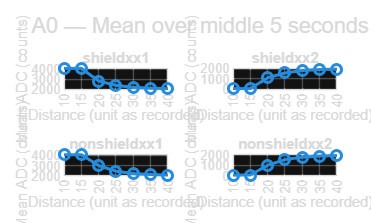

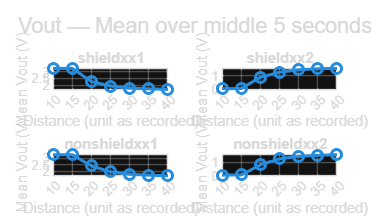

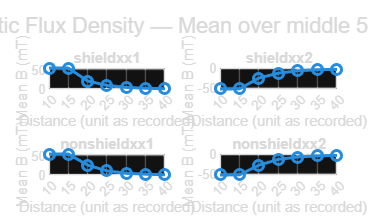

groups = ["shield", "nonshield"];
suffixes = ["1", "2"];

signals = ["A0", "Element3", "Element2"];
titles  = ["A0", "Vout", "Magnetic Flux Density"];
ylabels = ["Mean ADC (counts)", "Mean Vout (V)", "Mean B (mT)"];
scales  = [1, 1, 1000];

for k = 1:numel(signals)
    figure('Color', 'w', 'Name', char(titles(k)));
    tiledlayout(2, 2, 'TileSpacing', 'compact');

    for g = 1:numel(groups)
        for s = 1:numel(suffixes)
            distances = [];
            values = [];

            pattern = "^" + groups(g) + "(\d+)" + ...
                      suffixes(s) + "\." + signals(k) + "$";

            for i = 1:height(meansTable)
                token = regexp(string(meansTable.Variable(i)), ...
                               pattern, 'tokens', 'once');

                if isempty(token)
                    continue
                end

                distances(end+1) = str2double(token{1});

                value = meansTable.Mean(i);
                if iscell(value)
                    value = value{1};
                end
                values(end+1) = value * scales(k);
            end

            [distances, order] = sort(distances);
            values = values(order);

            nexttile;
            plot(distances, values, '-o', ...
                 'LineWidth', 1.8, 'MarkerSize', 6);
            grid on;
            xticks(distances);
            xlabel('Distance (unit as recorded)');
            ylabel(ylabels(k));
            title(groups(g) + "xx" + suffixes(s));
        end
    end

    sgtitle(titles(k) + " — Mean over middle 5 seconds");
end

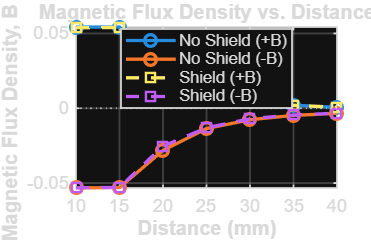

%% Magnetic Flux Density vs Distance
clearvars -except nonshield101 nonshield102 nonshield151 nonshield152 ...
    nonshield201 nonshield202 nonshield251 nonshield252 ...
    nonshield301 nonshield302 nonshield351 nonshield352 ...
    nonshield401 nonshield402 ...
    shield101 shield102 shield151 shield152 ...
    shield201 shield202 shield251 shield252 ...
    shield301 shield302 shield351 shield352 ...
    shield401 shield402

distance = [10 15 20 25 30 35 40];   % mm

% ===== Mean B from middle 5 seconds =====
% Element2 = Magnetic Flux Density [T]

% Non-shield
B_non_1 = [0.054238  0.054329  0.025613  0.010765 ...
    0.0044831 0.0020882 0.00057731];

B_non_2 = [-0.053319 -0.052994 -0.028213 -0.013556 ...
    -0.0076669 -0.0047637 -0.0034331];

% Shield
B_shield_1 = [0.053839  0.053971  0.020553  0.009259 ...
    0.0041034 0.0019527 0.00067663];

B_shield_2 = [-0.053185 -0.052931 -0.025338 -0.013059 ...
    -0.0069915 -0.0044873 -0.0033233];

%% Plot
figure('Color','w','Position',[200 150 850 550]);

plot(distance, B_non_1, '-o', ...
    'LineWidth', 2, 'MarkerSize', 7);
hold on;

plot(distance, B_non_2, '-o', ...
    'LineWidth', 2, 'MarkerSize', 7);

plot(distance, B_shield_1, '--s', ...
    'LineWidth', 2, 'MarkerSize', 7);

plot(distance, B_shield_2, '--s', ...
    'LineWidth', 2, 'MarkerSize', 7);

yline(0, ':', 'LineWidth', 1);

grid on;
box on;

xlabel('Distance (mm)', ...
    'FontSize', 12, 'FontWeight','bold');

ylabel('Magnetic Flux Density, B (T)', ...
    'FontSize', 12, 'FontWeight','bold');

title('Magnetic Flux Density vs. Distance', ...
    'FontSize', 14, 'FontWeight','bold');

legend('No Shield (+B)', ...
    'No Shield (-B)', ...
    'Shield (+B)', ...
    'Shield (-B)', ...
    'Location','best');

set(gca, ...
    'FontSize', 11, ...
    'LineWidth', 1.1, ...
    'GridAlpha', 0.2);

xlim([10 40]);
xticks(distance);

hold off;

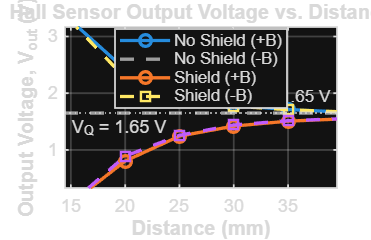

%% Vout vs Distance

distance = [10 15 20 25 30 35 40];   % mm

% ===== Vout [V] =====

% Non-shield
V_non_1 = [3.2771 3.2799 2.4184 1.9729 ...
    1.7845 1.7126 1.6673];

V_non_2 = [0.050434 0.060187 0.80362 1.2433 ...
    1.4200 1.5071 1.5470];

% Shield
V_shield_1 = [3.2652 3.2691 2.2666 1.9278 ...
    1.7731 1.7086 1.6703];

V_shield_2 = [0.054443 0.062080 0.88986 1.2582 ...
    1.4403 1.5154 1.5503];

%% Plot
figure('Color','w','Position',[200 150 850 550]);

plot(distance, V_non_1, '-o', ...
    'LineWidth', 2, 'MarkerSize', 7);
hold on;
% VQ reference line
VQ = 1.65;

yline(VQ, '--', 'V_Q = 1.65 V', ...
    'LineWidth', 2, ...
    'FontSize', 11, ...
    'LabelHorizontalAlignment', 'left', ...
    'LabelVerticalAlignment', 'bottom');
plot(distance, V_non_2, '-o', ...
    'LineWidth', 2, 'MarkerSize', 7);

plot(distance, V_shield_1, '--s', ...
    'LineWidth', 2, 'MarkerSize', 7);

plot(distance, V_shield_2, '--s', ...
    'LineWidth', 2, 'MarkerSize', 7);

% Quiescent voltage ~ VCC/2
yline(1.65, ':', 'V_Q = 1.65 V', ...
    'LineWidth', 1.2);

grid on;
box on;

xlabel('Distance (mm)', ...
    'FontSize', 12, 'FontWeight','bold');

ylabel('Output Voltage, V_{out} (V)', ...
    'FontSize', 12, 'FontWeight','bold');

title('Hall Sensor Output Voltage vs. Distance', ...
    'FontSize', 14, 'FontWeight','bold');

legend('No Shield (+B)', ...
    'No Shield (-B)', ...
    'Shield (+B)', ...
    'Shield (-B)', ...
    'Location','best');

set(gca, ...
    'FontSize', 11, ...
    'LineWidth', 1.1, ...
    'GridAlpha', 0.2);

xlim([10 40]);
xticks(distance);
ylim([0 3.4]);

hold off;